% The steps of the project

% 1. Face Detection: Use face detection algorithms to find the face within the image.
% 2. Feature Detection: Apply feature detection algorithms to locate the eyes and mouth.
% 3. Geometric Transformation: Apply transformations to rotate, scale, and translate the image so that the eyes (and if possible, the mouth) are aligned to a standard template.
% 4. Cropping and Resizing: Crop the aligned face to a standard size and resize it if necessary.
% 5. PCA and Eigenface Generation: Once the images are normalized and aligned, proceed with PCA and eigenface generation as you've already done.
% 6. Recognition: When a new image is received, apply the same preprocessing steps to it before projecting it onto the eigenface space for recognition.

addpath('functions');

% Main-file
% img1 = imread("images/DB1/db1_01.jpg");
% img2 = imread("images/DB1/db1_02.jpg");
% img3 = imread("images/DB1/db1_03.jpg");

% PART 1 (purpose to find eyes)

% Load dataset

% Skin detection? (DB2)

% Illuminant compensation

% White balance

% Image color correction?

% Convert to YCbCR (combine with HSV?)

% Face mask

% Detect face

% % ginput, BOB lab 1. Level slicing

% Eye map: Chrominance & Luminance

% Mouth map?

% Eye mask + face mask (grade 5)

% Normilization

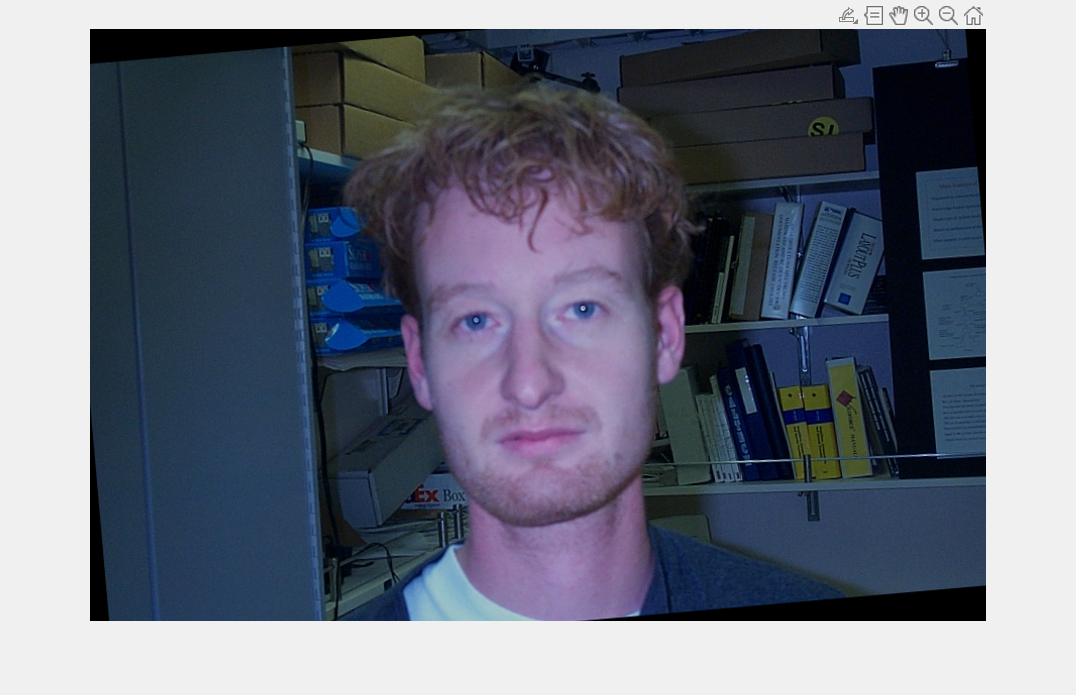

addpath('Functions');

img=imread('Images/DB2/bl_10.jpg');
%imshow(img);

img_deg=degrade_img(img);
%imshow(img_deg);

img_comp=rotation_compensation(img_deg);

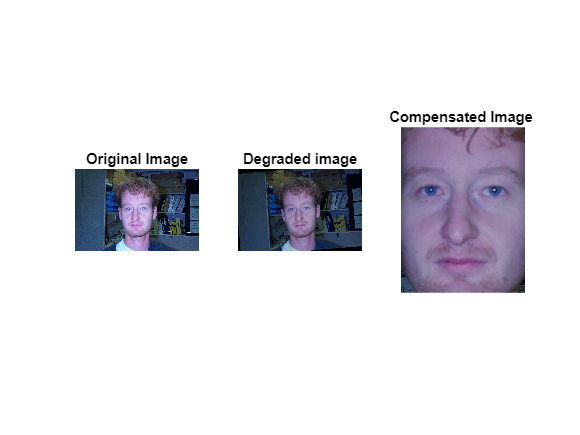

img_comp=tone_compensation(img_comp);
%imshow(img_comp)

 %Display the original, scaled, and rotated images (optional)
    figure;
    subplot(1, 3, 1);
    imshow(img);
    title('Original Image');
    
    subplot(1, 3, 2);
    imshow(img_deg);
    title('Degraded image');

    subplot(1, 3, 3);
    imshow(img_comp);
    title('Compensated Image ');

addpath('functions');

% Parameters
numImages = 16;
commonSize = [400, 300];
folderPath = 'images/DB1';
threshold = 0.90;  % Threshold for variance explanation

% Load and preprocess images
[dataMatrix, imageFiles] = load_and_preprocess_images(folderPath, commonSize);

% Perform PCA
[score, meanFace, numEigenfaces, eigenfaces, numComponentsRequired] = perform_pca(dataMatrix, threshold);

% Display number of components required
fprintf('Number of principal components needed: %d\n', numComponentsRequired);

Number of principal components needed: 10


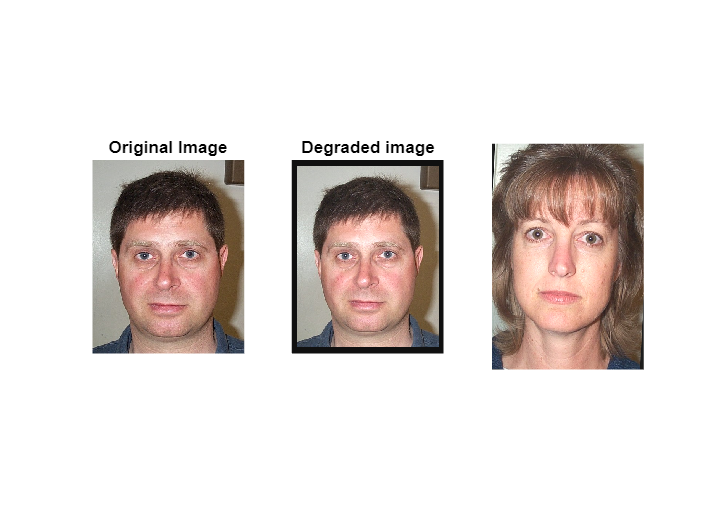

% Project query image onto eigenfaces
% DB1
queryImagePath = 'images/DB1/db1_07.jpg';

% DB2
% queryImagePath = 'images/DB2/bl_01.jpg';
editedImage = degrade_img(imread(queryImagePath));
imshow(editedImage);

The query image matches with image #7 in the training set.


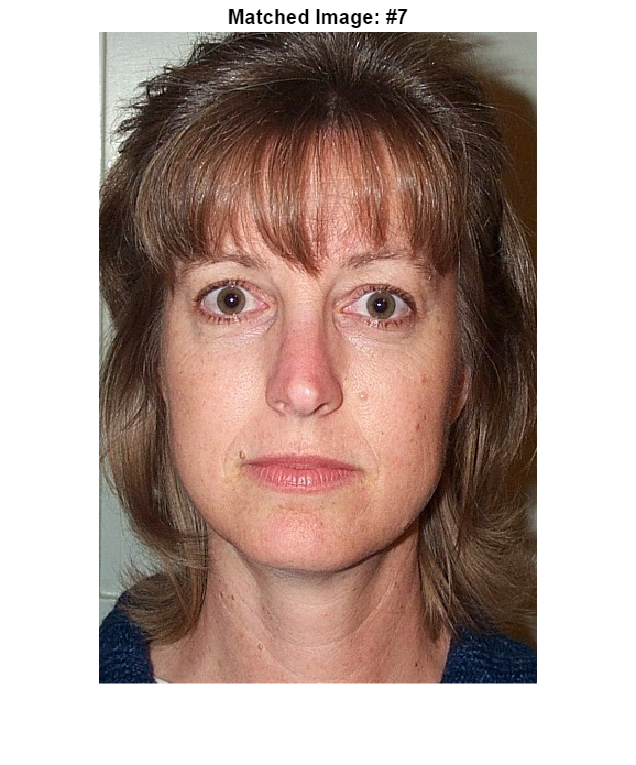

queryWeights = project_onto_eigenfaces(queryImagePath, eigenfaces, meanFace, commonSize);

% Recognize the face
recognize_face(queryWeights, score, numImages, folderPath, imageFiles, numEigenfaces);